clc
clear


## Load Database

db_images = loaddatabase(1);

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16



## Generate Eigenfaces

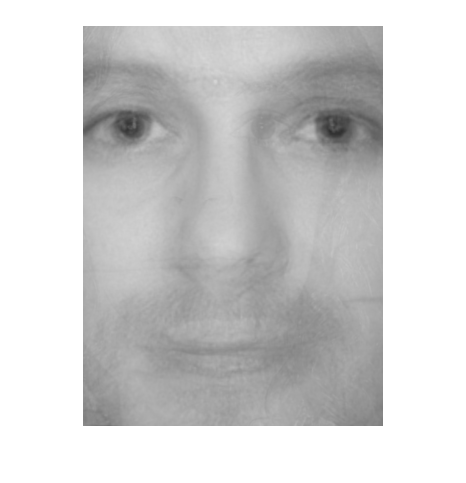

[u_i, meanface] = eigenfaces(db_images);

## Generate Feature vectors

for j = 1:size(db_images,3)
    fW = getFeatureVector(db_images(:,:,j), u_i, meanface);
    featureVectors(:,j) = fW(:);
end


## Load new image, rotate 5 degrees and test

correct_amount = 0;

folder = "Images" + "/DB1/";

for i = 1:1:16
    %Load images
    path = folder + "db1_" + sprintf('%02d',i) + ".jpg";
    current_image = imread(path);
    
    %rotate 5 degrees
    current_image = imrotate(current_image, 5, "crop");
    current_image = normalizeface(current_image);
    %figure;
    %imshow(current_image);
    %Get feature vector of input
    input_featureVector = getFeatureVector(current_image, u_i, meanface);
    
    %Find shortest distance (best match)
    for j = 1:16
        distances(:,j) = norm(input_featureVector(:) - featureVectors(:,j));
    end
    
    answer = find(distances == min(min(distances)));
    disp("Image: " + i + ", Answer: " + answer);

    if(i == answer)
        correct_amount = correct_amount + 1;
    end
end

Image: 1, Answer: 1
Image: 2, Answer: 2
Image: 3, Answer: 3
Image: 4, Answer: 4
Image: 5, Answer: 5
Image: 6, Answer: 6


Image: 7, Answer: 7
Image: 8, Answer: 8
Image: 9, Answer: 9
Image: 10, Answer: 10
Image: 11, Answer: 11
Image: 12, Answer: 12
Image: 13, Answer: 13
Image: 14, Answer: 14
Image: 15, Answer: 15
Image: 16, Answer: 16




% 1,6
% 2,7
% 3,14
% 4,4
% 5,5
% 6,6
% 7,7
% 8,8
% 9,9
% 10,10
% 11,4
% 12,5
% 13,13
% 14,14
% 15,15
% 16,16

disp("Accuracy: " + (correct_amount/16));

Accuracy: 1


disp("Correct images: " + correct_amount);

Correct images: 16
